# Chapter 2 Homework (Robotics)

I3 = eye(3);
syms theta phi

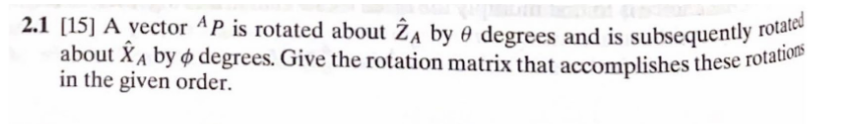

Fixed frame rotation (left to right) -> R = Rx•Rz

R_x = [1 0 0; 0 cos(phi) -sin(phi); 0  sin(phi) cos(phi)]

$$R\_x = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\varphi \right) & -\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

R_z = [cos(theta)  -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1]

$$R\_z = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$


R = R_x * R_z

$$R = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \cos\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\sin\left(\varphi \right)\\ \sin\left(\varphi \right)\,\sin\left(\theta \right) & \cos\left(\theta \right)\,\sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

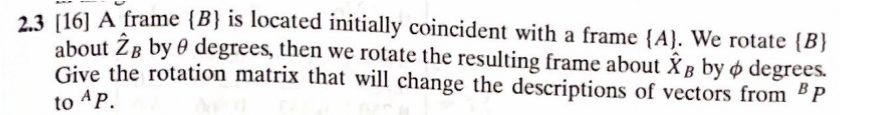

Moving frame rotation (right to left) -> R = Rz•Rx

R = R_z * R_x

$$R = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\cos\left(\varphi \right)\,\sin\left(\theta \right) & \sin\left(\varphi \right)\,\sin\left(\theta \right)\\ \sin\left(\theta \right) & \cos\left(\varphi \right)\,\cos\left(\theta \right) & -\cos\left(\theta \right)\,\sin\left(\varphi \right)\\ 0 & \sin\left(\varphi \right) & \cos\left(\varphi \right) \end{array}\right)$$

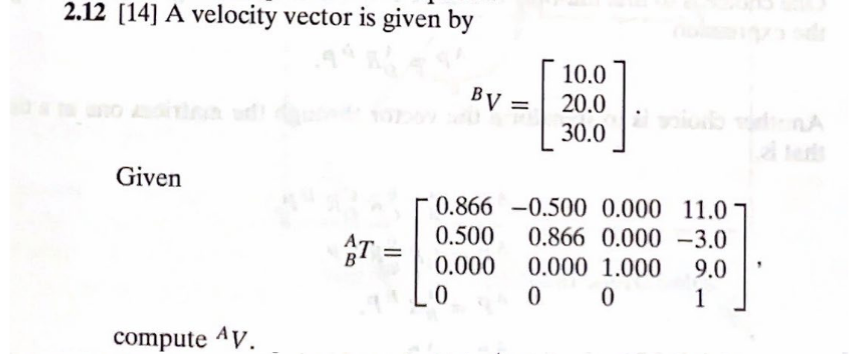

First thought: Velocity should be the same irrespective of where is "within" the frame. The fact that it's the derivative of position proves this.

BV = [10 20 30]'

BV =     10
    20
    30


ARB = [sqrt(3)/2 -0.5 0; 0.5 sqrt(3)/2 0 ; 0 0 1]

ARB =     0.8660   -0.5000         0
    0.5000    0.8660         0
         0         0    1.0000


AV = ARB * BV

AV =    -1.3397
   22.3205
   30.0000


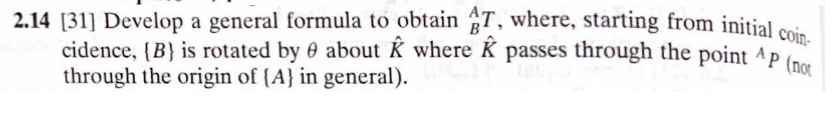

Intuition: The rotation matrix is the Equivalent Angle-Axis (from Euler's theorem). the bottom row is [0 0 0 1]. To find is the 3x1 vector describing the positional shift. This by its nature has to depend on the orientation of the axis K_hat, as well as the location of the point A_P.

Construct a matrix as follows:

the top 3x3 grid is equivalent to R_k(theta) 

Find the position vector AP_BORG, which is both translated and rotated

syms R_k(theta) 3 matrix 
syms Q_hat [3 1]
syms Q [3 1]

R_k_theta = R_k(theta)

$$R\_k\_theta = R_{k}\left(\theta \right)$$

ATB = symmatrix2sym([R_k_theta, Q_hat; zeros(1,3), 1])

$$ATB = \left(\begin{array}{cccc} R_{\mathrm{k1},1}\left(\theta \right) & R_{\mathrm{k1},2}\left(\theta \right) & R_{\mathrm{k1},3}\left(\theta \right) & Q_{\mathrm{hat1}}\\ R_{\mathrm{k2},1}\left(\theta \right) & R_{\mathrm{k2},2}\left(\theta \right) & R_{\mathrm{k2},3}\left(\theta \right) & Q_{\mathrm{hat2}}\\ R_{\mathrm{k3},1}\left(\theta \right) & R_{\mathrm{k3},2}\left(\theta \right) & R_{\mathrm{k3},3}\left(\theta \right) & Q_{\mathrm{hat3}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

R_k_theta = ATB(1:3,1:3)

$$R\_k\_theta = \left(\begin{array}{ccc} R_{\mathrm{k1},1}\left(\theta \right) & R_{\mathrm{k1},2}\left(\theta \right) & R_{\mathrm{k1},3}\left(\theta \right)\\ R_{\mathrm{k2},1}\left(\theta \right) & R_{\mathrm{k2},2}\left(\theta \right) & R_{\mathrm{k2},3}\left(\theta \right)\\ R_{\mathrm{k3},1}\left(\theta \right) & R_{\mathrm{k3},2}\left(\theta \right) & R_{\mathrm{k3},3}\left(\theta \right) \end{array}\right)$$

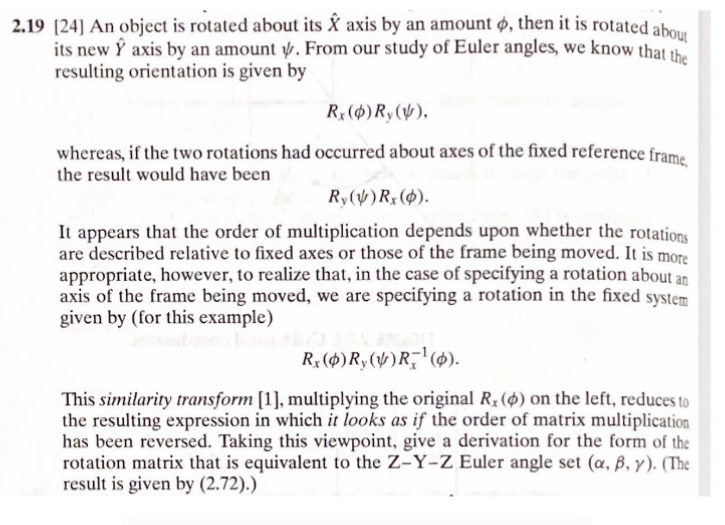

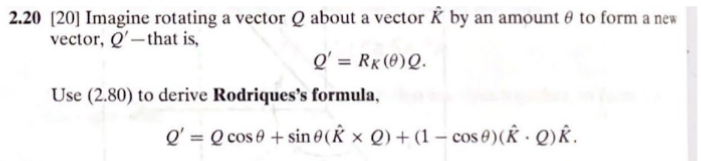

syms k_x k_y k_z
syms Q [3 1]
versine = @(x) 1-cos(x);
k = [k_x ; k_y; k_z]

$$k = \left(\begin{array}{c} k_{x}\\ k_{y}\\ k_{z} \end{array}\right)$$

k_matrix = [k_x 0 0; 0 k_y 0 ; 0 0 k_z] ;
assume(k,'real')
assume(Q,'real')
versine_component = k_matrix * [k_x k_y k_z; k_x k_y k_z ; k_x k_y k_z] 

$$versine\_component = \left(\begin{array}{ccc} {k_{x}}^{2} & k_{x}\,k_{y} & k_{x}\,k_{z}\\ k_{x}\,k_{y} & {k_{y}}^{2} & k_{y}\,k_{z}\\ k_{x}\,k_{z} & k_{y}\,k_{z} & {k_{z}}^{2} \end{array}\right)$$

cosine_component = eye(3)

cosine_component =      1     0     0
     0     1     0
     0     0     1


sine_component = [0 -k_z k_y ; k_z 0 -k_x; -k_y k_x 0]

$$sine\_component = \left(\begin{array}{ccc} 0 & -k_{z} & k_{y}\\ k_{z} & 0 & -k_{x}\\ -k_{y} & k_{x} & 0 \end{array}\right)$$

R_k_theta = versine(theta) * versine_component + cos(theta) * cosine_component + sin(theta) * sine_component; 

When taking Rk(θ)•Q, we get the following from a component breakdown (noting that matrix multiplication, as well as scalar multiplication with a matrix, are distributive):

• The cosine component is the identity matrix -> IQ = Q

• The sine component is simply the matrix form of the cross product with the vector K -> sine_component * Q = K x Q

• Q times the versine component is 

versine_component

$$versine\_component = \left(\begin{array}{ccc} {k_{x}}^{2} & k_{x}\,k_{y} & k_{x}\,k_{z}\\ k_{x}\,k_{y} & {k_{y}}^{2} & k_{y}\,k_{z}\\ k_{x}\,k_{z} & k_{y}\,k_{z} & {k_{z}}^{2} \end{array}\right)$$

Corresponding to 

k * k'

$$ans = \left(\begin{array}{ccc} {k_{x}}^{2} & k_{x}\,k_{y} & k_{x}\,k_{z}\\ k_{x}\,k_{y} & {k_{y}}^{2} & k_{y}\,k_{z}\\ k_{x}\,k_{z} & k_{y}\,k_{z} & {k_{z}}^{2} \end{array}\right)$$

Which when multiplied with Q gives us

(k * k') * Q

$$ans = \left(\begin{array}{c} Q_{1}\,{k_{x}}^{2}+Q_{2}\,k_{x}\,k_{y}+Q_{3}\,k_{x}\,k_{z}\\ Q_{2}\,{k_{y}}^{2}+Q_{1}\,k_{x}\,k_{y}+Q_{3}\,k_{y}\,k_{z}\\ Q_{3}\,{k_{z}}^{2}+Q_{1}\,k_{x}\,k_{z}+Q_{2}\,k_{y}\,k_{z} \end{array}\right)$$

Because matrix multiplication is associative, we can pull the brackets to the right 2 terms instead

k * (k' * Q)

$$ans = \left(\begin{array}{c} k_{x}\,\left(Q_{1}\,k_{x}+Q_{2}\,k_{y}+Q_{3}\,k_{z}\right)\\ k_{y}\,\left(Q_{1}\,k_{x}+Q_{2}\,k_{y}+Q_{3}\,k_{z}\right)\\ k_{z}\,\left(Q_{1}\,k_{x}+Q_{2}\,k_{y}+Q_{3}\,k_{z}\right) \end{array}\right)$$

And now, because the value in the brackets is a scalar, we can put it in front of k to get closer to the original form we want (since scalar multiplication is commutative)

(k' * Q) * k

$$ans = \left(\begin{array}{c} k_{x}\,\left(Q_{1}\,k_{x}+Q_{2}\,k_{y}+Q_{3}\,k_{z}\right)\\ k_{y}\,\left(Q_{1}\,k_{x}+Q_{2}\,k_{y}+Q_{3}\,k_{z}\right)\\ k_{z}\,\left(Q_{1}\,k_{x}+Q_{2}\,k_{y}+Q_{3}\,k_{z}\right) \end{array}\right)$$

By definition, the dot product of k and Q is k_(1x3) * Q_(3x1) . Therefore, we have now proven that the versine component is equivalent to (k • Q) * k. 

We can then use the distributive property of matrix multiplication to say that 

Rk(θ) * Q = (v(θ)*versine_component_rkθ +  cos(θ)*cosine_component_rkθ + sin(θ)*sine_component) * Q = [Rodrigues' formula] QED.

cos(θ) = 1 -> v(θ) = 0

sin(θ) = θ

Remove all versine terms, and replace sin of theta with theta

r_k_small_theta = subs(R_k_theta,[sin(theta) cos(theta)],[theta 1])

$$r\_k\_small\_theta = \left(\begin{array}{ccc} 1 & -k_{z}\,\theta & k_{y}\,\theta \\ k_{z}\,\theta & 1 & -k_{x}\,\theta \\ -k_{y}\,\theta & k_{x}\,\theta & 1 \end{array}\right)$$

Which can also be written as 

I_3 + [K]_x * θ

Rk1 = I_3 + [K1]_x * θ

Rk2 = I_3 + [K2]_x * θ

Rk1 * Rk2 = (I_3 + [K1]_x * θ)(I_3 + [K2]_x * θ) = I_3 + [K1]_x * θ  + [K2]_x * θ + [K1]_x [K2]_x * θ^2  

Cancel the θ^2 term ->  all other terms are scalar multiples making both orders equivalent

syms k1 k2 [3 1] 
rk1 = subs(r_k_small_theta, k, k1)

$$rk1 = \left(\begin{array}{ccc} 1 & -k_{13}\,\theta & k_{12}\,\theta \\ k_{13}\,\theta & 1 & -k_{11}\,\theta \\ -k_{12}\,\theta & k_{11}\,\theta & 1 \end{array}\right)$$

rk2 = subs(r_k_small_theta, k, k2)

$$rk2 = \left(\begin{array}{ccc} 1 & -k_{23}\,\theta & k_{22}\,\theta \\ k_{23}\,\theta & 1 & -k_{21}\,\theta \\ -k_{22}\,\theta & k_{21}\,\theta & 1 \end{array}\right)$$

Subtract them from each other, replacing θ^2 with 0 -> they're the same

subs(rk1*rk2 - rk2 * rk1,theta^2,0)

$$ans = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

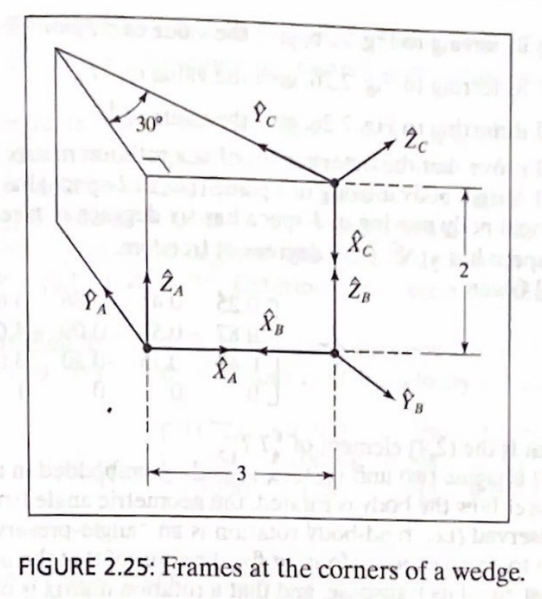

Shift: +3 in the X direction of B (AP_B,org = [3 0 0]')

Y_A = -Y_B

X_A = -X_B

Z_A = Z_B 

Fill in column vectors as such.

(Can also write this as a π rotation about Z, but this is simpler since we can do it visually)

AR_B = [-1 0 0 ; 0 -1 0 ; 0 0 1]'

AR_B =     -1     0     0
     0    -1     0
     0     0     1


AT_B = [AR_B , [3 0 0]' ; 0 0 0 1]

AT_B =     -1     0     0     3
     0    -1     0     0
     0     0     1     0
     0     0     0     1


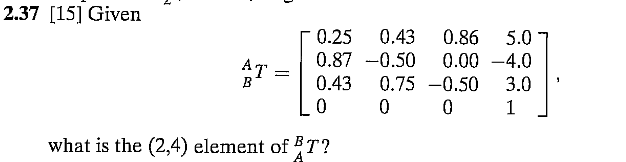

AT_B = [0.25 0.43 0.86 5.0; 0.87 -0.5 0 -4; 0.43 0.75 -0.5 3 ; 0 0 0 1]

AT_B =     0.2500    0.4300    0.8600    5.0000
    0.8700   -0.5000         0   -4.0000
    0.4300    0.7500   -0.5000    3.0000
         0         0         0    1.0000



AR_B = AT_B(1:3,1:3)

AR_B =     0.2500    0.4300    0.8600
    0.8700   -0.5000         0
    0.4300    0.7500   -0.5000


BT_A = [AR_B , -AR_B' * AT_B(1:3,4); 0 0 0 1]

BT_A =     0.2500    0.4300    0.8600    0.9400
    0.8700   -0.5000         0   -6.4000
    0.4300    0.7500   -0.5000   -2.8000
         0         0         0    1.0000


BT_A(2,4)

ans = -6.4000

The answer is -6.4

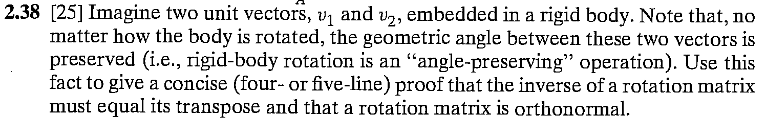

For some rotation R, we are given that the angle is preserved between vectors. This means that the dot product is also preserved since they are both unit vectors.

This means, v1 • v2 = Rv1 • Rv2 , equivalent to (Rv1)^T * Rv2

since (AB)^T = B^T A^T we can rewrite this as v1^T R^T R v2 

For this to hold true, R^T * R must be equal to I. In other words, R's transpose must also be its inverse